addpath('functions/');

% Creating n Corticalspinal cells
n = 1000; 

% Initalize the base CS cells
% 80% of the n Cortical cells are M1
m1_count = n * 0.8;
m1_destroyed = m1_count * 0.5;
m1_alive = m1_count * 0.5;
m1 = [zeros(1, m1_destroyed), rand(1, m1_alive)];

x_0 = [m1, sma];

% Parameters for zero-mean normal distribution
std_dev = 0.02;
mean = 0;

% CS extensor and flexor connection weights
flexor_c_fi = [ones(1, n)]; 
flexor_c_ei = [zeros(1, n*0.7), -ones(1, n*0.3)]; 
extensor_c_ei = [ones(1, n)]; 
extensor_c_fi = [zeros(1, n*0.7), -ones(1, n*0.3)]; 

% Translating MN pool to force
delta = 1;

final_forces_m1 = [];
trials = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    m1_v_i = std_dev.*randn(1, m1_count) + mean;
    m1_i = m1 + m1_v_i;

    for i = 1:m1_destroyed
        % Ensure CS M1 cells are destroyed (0)
        m1_i(i) = 0;
    end

    % Flexor MN Pools translated to force
    s_fi = 0;
    for i = 1:m1_count
        % M1
        temp = g_i(m1_i(i), flexor_c_w(i));
        s_fi = s_fi + temp;
    end
    f_f = delta * s_fi;
    
    % Extensor MN Pools translated to force
    s_ei = 0;
    for i = 1:m1_count
        % M1
        temp = g_i(m1_i(i), extensor_c_w(i));
        s_ei = s_ei + temp;
    end
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    if f_net > f_final_net
        f_final_net = f_net;
        m1 = m1_i;
    end

    trials = [trials, trial];
    final_forces_m1 = [final_forces_m1, f_final_net];
end

Unrecognized function or variable 'm1'.

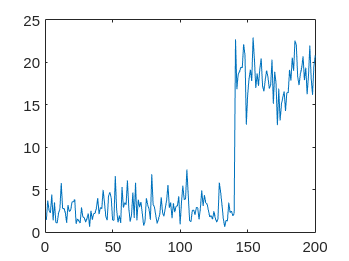


% 20& of the n Cortical cells are SMA
sma_count = n * 0.2;
sma = rand(1, sma_count);
sma_initial = sma;

% CS extensor and flexor connection weights
% For flexor CS cells, we set the weights  and  to be +1 and 0 for 70% of cells, and +1 and −1 for 30% of cells
flexor_c_w = [ones(1, sma_count)]; 
extensor_c_w = [zeros(1, sma_count*0.7), -ones(1, sma_count *0.3)]; 

final_forces_sma = [];
trials = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    sma_v_i = std_dev.*randn(1, sma_count) + mean;
    sma_x_i = sma + sma_v_i;


    % Flexor MN Pools translated to force
    s_fi = 0;
    for i = 1:sma_count
        % SMA
        temp = 0.1 * g_fi(sma_x_i(i), flexor_c_w(i));
        s_fi = s_fi + temp;
    end
    f_f = delta * s_fi;
    
    % Extensor MN Pools translated to force
    s_ei = 0;
    for i = 1:sma_count
        % SMA
        temp = 0.1 * g_ei(sma_x_i(i), extensor_c_w(i));
        s_ei = s_ei + temp;
    end
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    if f_net > f_final_net
        f_final_net = f_net;
        sma = sma_x_i;
    end

    final_forces_sma = [final_forces_sma, f_final_net];
end

plot(sma)

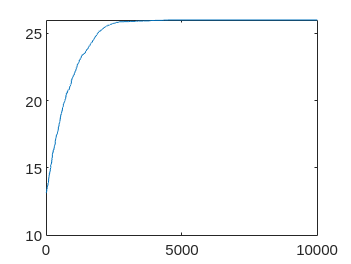

plot(final_forces_sma)

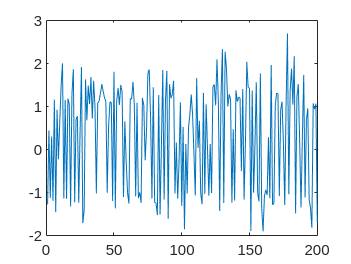

plot(x_0)

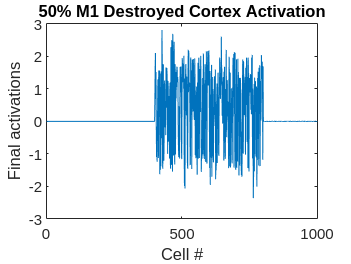

%hold on
%plot(10 * ones(1, m1_count))
%hold off
title("50% M1 Destroyed Cortex Activation")
%ylim([0, 15])
ylabel("Final activations")
xlabel("Cell #")

saveas(gcf, 'images/M1Destroyed50Activations.png')

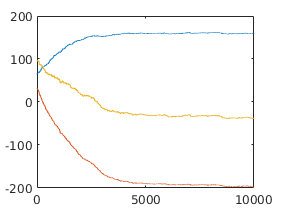

plot([1:10000], f_fs, [1:10000], f_es, [1:10000], f_fs + f_es)

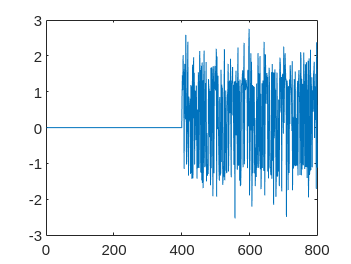

plot(m1)

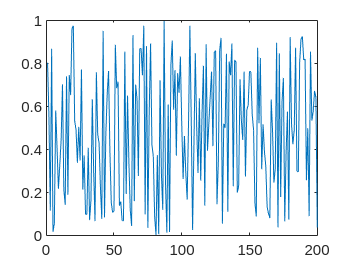

plot(sma)

function s = g_fi(c_i, x_i)
    % Positive Saturation Limit
    s = c_i * x_i;
    if c_i > 0 && s > 1
        s = +1;
    end
end

function s = g_ei(c_i, x_i)
    % Negative Saturation Limit
    s = c_i * x_i;
    if c_i < 0 && s < -1
        s = -1;
    end
end